data_Txy = readmatrix("Result\Tyz\wave10_Tyz_2500.csv")

data_Txy =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

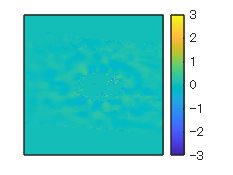

imagesc(data_Txy);
caxis([-3 3]);
axis image;
cb = colorbar;
ax = gca;
ax.XTick = [];
ax.YTick = [];

cb.FontSize = 10;

csvDir = "Result/Tyz/";
files = dir(fullfile(csvDir, "*.csv"));

hit = strings(0);
for k = 1:numel(files)
    fp = fullfile(csvDir, files(k).name);
    M = readmatrix(fp);
    if any(M(~isnan(M)) ~= 0, "all")
        hit(end+1) = fp; %#ok<SAGROW>
    end
end

disp(hit)   % 該当ファイルのフルパス一覧
